# Dual-pixel autofocus sensor simulation

We illustrate how to create a dual pixel sensor for autofocus applications.  

The dual pixel design consists of a sensor with rectangular pixels that are twice as high as wide (see below).  There is a microlens over each pixel that directs light from the left half of the lens to the right pixel, and right half of the lens to the left pixel. This forms two independent images, seen through the right and left side of the lens.   

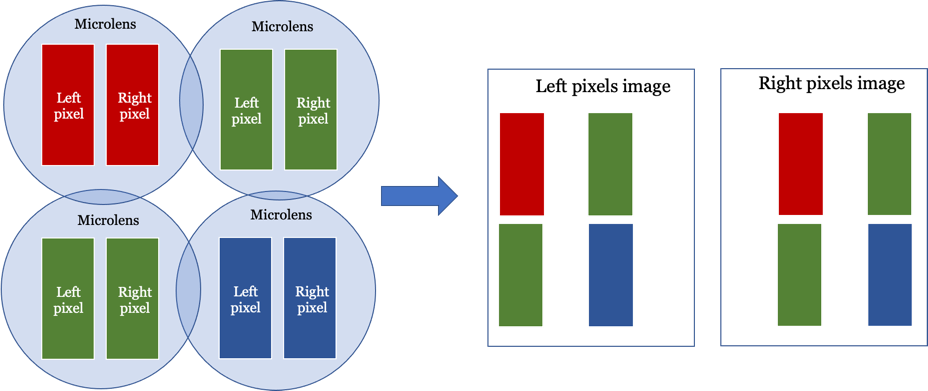

In regions where the focus is good, the left and right images have the same value.  But in regions where there is defocus, the left and right images do not have the same value.  

Using signal processing methods, we can detect the regions where the left and right image values are the same.  By adjusting the distance of the sensor from the lens, we make different regions in the left and right image match.  By choosing which regions match, we focusing that region of the image.

**See also:**

  s_sensorDPAF (ISETCam), tls_casmeraLightField.mlx

## Initialize

ieInit;
if ~piDockerExists, piDockerConfig; end
chdir(fullfile(piRootPath,'local'));

## Read the chess set scene

thisR = piRecipeDefault('scene name','chessSet');

Read 9 materials.
Read 3 textures.
***Scene parsed.


## Set up the combined imaging and microlens array

Make sure you have isetlens on your path!

uLensName = 'microlens.json';           % Microlens model
iLensName = 'dgauss.22deg.3.0mm.json';  % Imaging lens

% The pixel width (below) is 1.4 um. The microlens covers two pixels
uLensDiameter = 0.0028;         % 2.8 um - each covers the dual pixels
nMicrolens    = [128 128];      % There will be this many dual pixels

% This calls the docker container to create the combinedLensFile, which is
% a JSON description of the iLens and uLens.
[combinedLensFile, uLens, iLens] = lensCombine(uLensName,iLensName,uLensDiameter,nMicrolens);

Overwriting dgauss.22deg.3.0mm.json
Overwriting microlens.json

------
Microlens insertion summary
Microlens dimensions 128 128 
Microlens to film distance 0.005045
Film height and width 1.000000 1.000000
------
Imaging lens copy exists.  Not over-writing
Microlens copy exists.  Not over-writing
Mounting folder C:\iset\iset3d-v4\local
/iset/iset3d-v4/local/dgauss.22deg.3.0mm.json + /iset/iset3d-v4/local/microlens.json = /iset/iset3d-v4/local/dgauss.22deg.3.0mm+microlens.json



thisR.camera = piCameraCreate('omni','lensFile',combinedLensFile);

## Set up the film parameters

We want the OI to have adequate spatial resolution.  We set it up here to calculate the irradiance at 4 positions for each microlens, and thus two positions for each of the pixels. The pair of up/down positions will be summed by the sensor into a single pixel response. The pair of left/right positions will be used to calculate the signal incident at the two pixels behind the microlens.

pixelsPerMicrolens = 2;
halfPixelWidth_mm = uLens.get('lens diameter')/pixelsPerMicrolens;    % mm

% The total film (sensor) size.
filmwidth  = nMicrolens(2)*uLens.get('diameter','mm');       % mm
filmheight = nMicrolens(1)*uLens.get('diameter','mm');       % mm
filmresolution = [filmheight, filmwidth]/halfPixelWidth_mm;

% This is the size of the film/sensor in millimeters
thisR.set('film diagonal',sqrt(filmwidth^2 + filmheight^2));

% Film resolution -
thisR.set('film resolution',filmresolution);

% The desired spacing is halfPixelWidth_mm 
assert(thisR.get('sample spacing') == halfPixelWidth_mm);

% This is the aperture of the imaging lens of the camera in mm
thisR.set('aperture diameter',10);

% Adjust for quality
thisR.set('rays per pixel',20);


#### Set the focus distance to the back of the scene

dRange = thisR.get('depth range');   % Runs the docker to get the depth map

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.86
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   3.32
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   8.20
Complete render took: 1.35e+01 seconds.*** Rendering time for ChessSet:  13.5 sec ***

exr2bin done.

thisR.set('focus distance',2*dRange(2));

## Render

Write, render, and show the recipe.  The optical image is returned in oi.  We also confirm that the spatial samples in the oi will match the resolution of the sensor pixels.

oi = piWRS(thisR);

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.97
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Error Rendering: pbrt version 4 (built Jan 24 2022 at 20:16:23)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
terminate called after throwing an instance of 'nlohmann::detail::type_error'
  what():  [json.exception.type_error.302] type must be number, but is array
Aborted (core dumped)
Complete render took: 4.95e+00 seconds.

Status:
   134

Result:
pbrt version 4 (built Jan 24 2022 at 20:16:23)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
terminate called after throwing an instance of 'nlohmann::detail::type_error'
  what():  [json.exception.type_error.302] type must be number, but is array
Aborted (core dumped)

*** Rendering time for ChessSet:  4.9 sec ***



Error using piEXR2ISET (line 57)
The value of 'inputFile' is invalid. It must satisfy the function: @(x)(exist(x,'file')).

Error in piRender (line 267)
    ieObject = piEXR2ISET(outFile, 'recipe',thisR,'label',thisR.metadata.rendertype);

Error in piWRS (


ss = oiGet(oi,'sample spacing','mm');
assert(abs(ss(1) - halfPixelWidth_mm) < 10*eps);

## Make a dual pixel sensor that has r qqectangular pixels

sensor = sensorCreate('dual pixel',[],oi,nMicrolens);

## Compute the sensor data

Notice that we display the spatial structure of the image correctly, even though the pixels are rectangular.  That is magical programming behind the scene, where we know that the pixels are rectangular!

sensor = sensorCompute(sensor,oi);
sensor = sensorSet(sensor,'name','DPAF');
sensorWindow(sensor);

## Extract the left and right images from the dual pixel array

Every other pixel is left/right.

volts = sensorGet(sensor,'volts');
leftVolts = volts(1:end,1:2:end);
rightVolts = volts(1:end,2:2:end);

## Create sensors for left and right image

We take the left and right pixel voltages and place them into two different sensor structs.

leftSensor = sensorCreate;
leftSensor = sensorSet(leftSensor,'size',size(leftVolts));
leftSensor = sensorSet(leftSensor,'volts',leftVolts);
leftSensor = sensorSet(leftSensor,'name','left');

sensorWindow(leftSensor);

## Now the right pixel voltages.

rightSensor = sensorCreate;
rightSensor = sensorSet(rightSensor,'size',size(rightVolts));
rightSensor = sensorSet(rightSensor,'volts',rightVolts);
rightSensor = sensorSet(rightSensor,'name','right');
sensorWindow(rightSensor);

### Plot lines through the left and right sensor data

rightSensorData = sensorPlot(rightSensor,'electrons hline',[88 88]);
% sensorPlot(rightSensor,'electrons hline',[89 89]);
c = [1 176 89 89];
[shapeHandle,ax] = ieROIDraw('sensor','shape','line','shape data',c);
leftSensorData = sensorPlot(leftSensor,'electrons hline',[88 88]);
% sensorPlot(leftSensor,'electrons hline',[89 89]);

ieNewGraphWin;
plot(leftSensorData.pos{1},leftSensorData.data{1},'b-',...
    rightSensorData.pos{1},rightSensorData.data{1},'r-');
grid on; xlabel('Position (um)'); ylabel('Electrons');

### Sum the left and right and make an image

bothVolts = (leftVolts + rightVolts)/2;

sensorBoth = rightSensor;
sensorBoth = sensorSet(sensorBoth,'volts',bothVolts);
sensorBoth = sensorSet(sensorBoth,'name','Both');
sensorWindow(sensorBoth);

### Create an image processor view of the sum

ipBoth = ipCreate;
ipBoth = ipCompute(ipBoth,sensorBoth);
ipWindow(ipBoth);

### Compare the left and right image views 

leftip = ipCreate;
leftip = ipCompute(leftip,leftSensor);
ipWindow(leftip);
leftuData = ipPlot(leftip,'horizontal line',[89 89]);

rightip = ipCreate;
rightip = ipCompute(rightip,rightSensor);
ipWindow(rightip);
rightuData = ipPlot(rightip,'horizontal line',[89 89]);

#### END